% 最初的探索时期的代码，保留很多探索时的痕迹，
% 不作过多的注释
clear

load('rir1.mat');
load('mic_position1.mat');

fs = 16e3

fs = 16000

p.micLocs = mic_position1'

p = 包含以下字段的 struct :
    micLocs: [7×3 double]

p.fs = fs;
p.c = 345;
p.winLen = 0;
p.parFrames = 8192;
p.showArray = 0;
RT60 = 1500;%ms

if iscell(rir1)
    % 获取cell数组的大小
    %[num_cells, ~, Len] = size(rir);
    [num_cells, ~] = size(rir1);
    % 初始化一个空矩阵来存储转换后的数据
    rir_length = [];

    % 循环遍历每个单元格
    for i = 1:num_cells
        Length = length(rir1{i});
        rir_length = [rir_length; Length];
    end
    limit_len = min(rir_length);
    rir_data = zeros(num_cells,limit_len);

    for i = 1:num_cells
        rir_data(i,:) = rir1{i}(1:limit_len);
    end
else
    %[~,~,l] = size(rir);
    rir_data = rir1;%reshape(rir, [7, l]); % 转换矩阵尺寸为 [7, N]
end
%rir_data = reshape(rir, [num_cells Len])

DOA{1} = SDMPar(rir_data',p);

Started SDM processing
Using frame size 18
Ended SDM processing in 0.14805 seconds.


P{1} = rir_data(7,:);

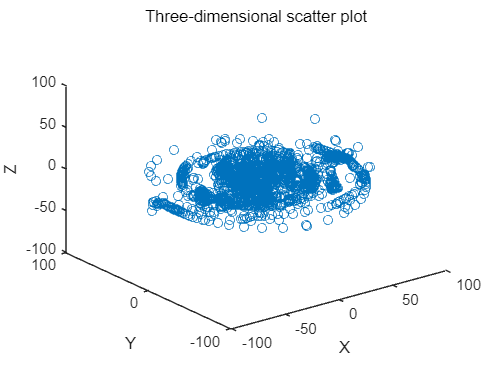

% 生成一个逻辑向量，指示哪些值是非 NaN 值
valid_indices = ~isnan(DOA{1});

% 使用逻辑索引选取非 NaN 值
valid_DOA = DOA{1}(valid_indices);
valid_DOA = reshape(valid_DOA, [], 3);
% 绘制散点图
figure;
plot3(valid_DOA(:,1), valid_DOA(:,2), valid_DOA(:,3), 'o');
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Three-dimensional scatter plot');

% 假设你的点集是 valid_DOA，其中包含了位置和幅度信息
% valid_DOA 应该是一个 n×3 的矩阵，每一行代表一个点的位置坐标 [x, y, z]，每个点的幅度信息可以存在另一个数组中

% 设置幅度信息，这里假设存储在叫做 amplitudes 的数组中
valid_amp_indice = valid_indices(:,1);
ori_amp = rir_data(7,:)

ori_amp =     0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000


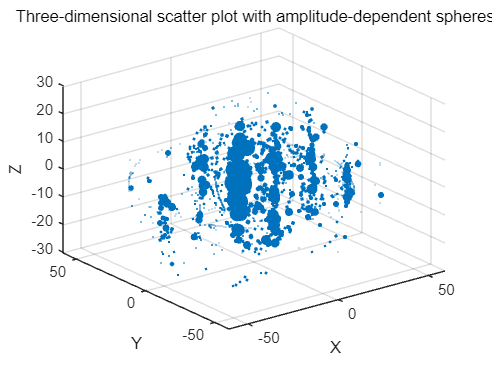

valid_amp = ori_amp(valid_amp_indice);
amplitudes = abs(valid_amp'); % 这里用随机数代替实际的幅度信息

% 将幅度信息映射到球的半径上
scaleFactor = 2e3;
% 可以根据具体需求设计一个合适的映射关系，这里简单地将幅度信息乘以一个系数作为半径
radius = amplitudes * scaleFactor; % scaleFactor 是一个缩放系数，用于调整球的大小

% 绘制散点图
figure;
scatter3(valid_DOA(:,1), valid_DOA(:,2), valid_DOA(:,3), radius', 'filled');
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Three-dimensional scatter plot with amplitude-dependent spheres');
% colorbar; % 添加颜色条，以显示幅度信息
hold on
% 读取STL文件
[vertices, faces, ~, ~] = stlread('D:\MATLAB\Matlab_HaHa\Degree_project\3D_model_file\zj425.stl');
room = triangulation(vertices.ConnectivityList, vertices.Points./1000);
% 显示STL模型
%trisurf(room, 'FaceColor', [0.8 0.8 0.8], 'FaceAlpha', 0.3, 'EdgeColor', 'none');
axis([-60 60 -60 60 -30 30])
hold off;

## 导出SDM镜像源与声压信号

%PointCloud_export(valid_DOA, valid_amp', 'ori', mic_position);


%plot([1:length(valid_amp)]/fs,abs(valid_amp))

%plot([1:length(rir_data(7,:))]/fs,abs(rir_data(7,:)))

%尝试聚类简化点云图
% num_clusters = 12000;
% [idx, centers] = kmeans(valid_DOA, num_clusters);

% new_DOA = centers;
% new_amp = kameans_trans(idx, valid_amp, num_clusters);

% %画聚类后的点云图
% pointcloud_plot(new_amp, new_DOA, scaleFactor)

% %导出聚类后的点云图
% PointCloud_export(new_DOA, new_amp', 'kmeans', mic_position);

% %尝试截取一下RIR
% cut_amp = valid_amp(1:(length(valid_amp)/3*2));
% cut_DOA = valid_DOA(1:(length(valid_amp)/3*2),:);
% scaleFactor = 2e3;
% pointcloud_plot(cut_amp, cut_DOA, scaleFactor)
% %导出截取后的点云图
% PointCloud_export(cut_DOA, cut_amp', 'cut',mic_position);

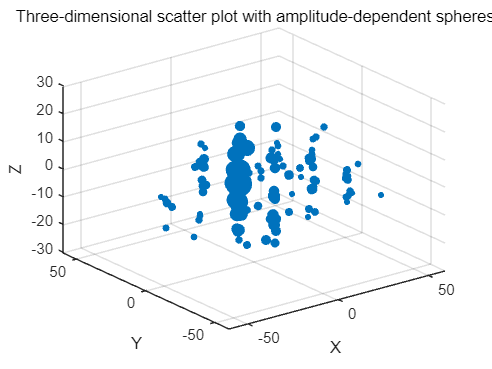

%尝试剔除幅值过小的点云
%幅值小于3e-4的可以被剔除%tips:用能量去筛选还是用幅值去筛选
% 计算直方图
[counts, edges] = histcounts(valid_amp.^2);
% 找到计数最多的组别的索引
[~, maxIndex] = max(counts);
% 获取具有最多计数的组别的范围
maxRange = [edges(maxIndex), edges(maxIndex + 1)];
pure_amp = [];
pure_DOA = [];
for i = 1:length(valid_amp)
    if abs(valid_amp(i)^2) >= abs(maxRange(2))/3*2
        pure_amp = [pure_amp, valid_amp(i)];
        pure_DOA = [pure_DOA; valid_DOA(i,:)];
    end
end
scaleFactor = 2e3;
pointcloud_plot(pure_amp, pure_DOA, scaleFactor)

%导出剔除后的点云图
%PointCloud_export(pure_DOA, pure_amp', 'pure_square',mic_position);

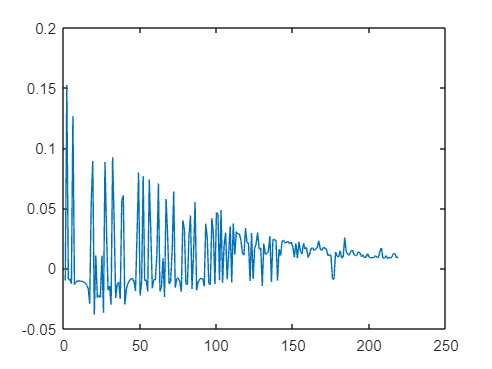

plot(pure_amp)

## 获取传输矩阵，尝试进行插值

PCld_1 = load("PointCloud_pure_square_8.mat");
PCld_2 = load("PointCloud_pure_square_20.mat");
T = load("T.mat");
log_emd = load("log_emd.mat");

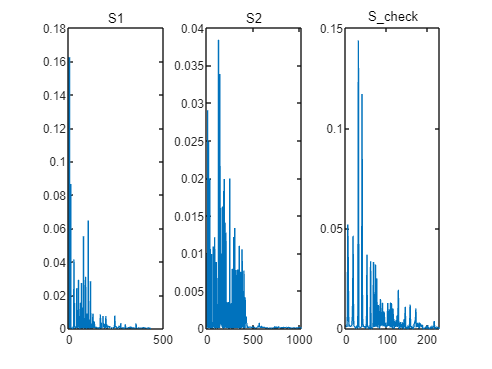

%检验传输矩阵的特性
figure
S1 = PCld_1.PointCloud(:,4).^2;
S2 = PCld_2.PointCloud(:,4).^2;
S_check = sum(T.T,1).^2;
subplot(1,3,1)
plot(S1./sum(S1))
title('S1')
subplot(1,3,2)
plot(S2./sum(S2))
title('S2')
subplot(1,3,3)
plot(S_check./sum(S_check))
title('S\_check')

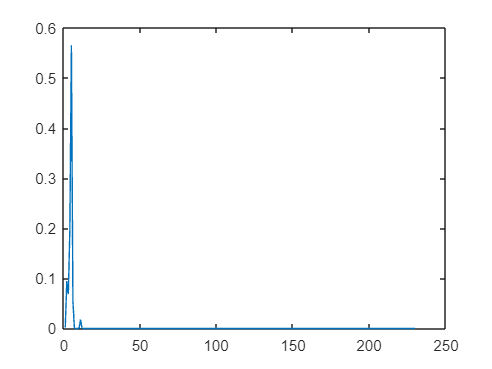

%观察标号2的xs点源的传输情况
figure
plot(T.T(2,:)/sum(T.T(2,:)))

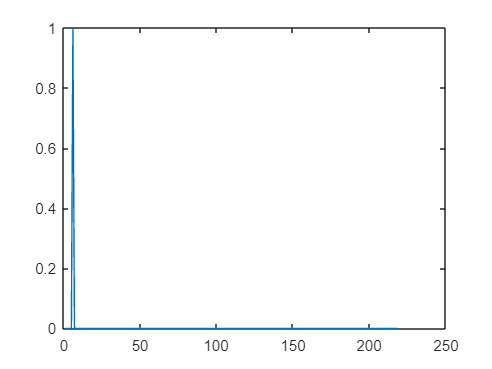

%观察标号为53的xt点源的接收情况
figure
plot(T.T(:,53)/sum(T.T(:,53)))

% figure
% histogram(T.T)
pure_T = T.T;
% figure
% matrix_show(pure_T);
% histogram(pure_T)
% axis([0 6e-3 0 0.5])

%pure_T(abs(pure_T)<2e-3)=0;

k = 1;%插入点的标号
k_ = 0.001;%插入点的比例系数
T_ = pure_T;
% matrix_show(T_)


% u = log_emd.log_emd.u;
% v = log_emd.log_emd.v;
% for i = 1:length(u)
%     if u(i) > 0
%         if sum(pure_T(i,:)) == 0
%             r(k) = (1-k_)*u(i);
%             z(k,:) = PCld_1.PointCloud(i,1:3);
%             k = k + 1;
%         else
%             T_(i,:) = T_(i,:) + (1-k_)*u(i)*pure_T(i,:)/sum(pure_T(i,:));
%         end
%     end
% end
% for j = 1:length(v)
%     if v(j) > 0
%         if sum(pure_T(:,j)) == 0
%             r(k) = k_*v(j);
%             z(k,:) = PCld_2.PointCloud(j,1:3);
%             k = k + 1;
%         else
%             T_(:,j) = T_(:,j) + k_*v(j)*pure_T(:,j)/sum(pure_T(:,j));
%         end
%     end
% end
[n,m] = size(T_);
for i = 1:n
    for j = 1:m
        if T_(i,j) > 0
            r(k) = T_(i,j);
            z(k,:) = (1-k_)*PCld_1.PointCloud(i,1:3)...
                + k_*PCld_2.PointCloud(j,1:3);
            k = k + 1;
        end
    end
end

% matrix_show(T_)

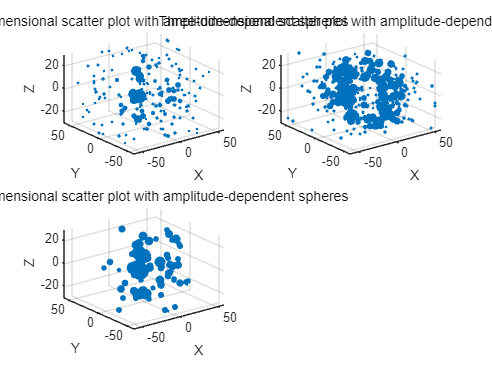

%插值所使用的点云图
PCld_1_energy = PCld_1.PointCloud(:,4)/sum(PCld_1.PointCloud(:,4));
PCld_2_energy = PCld_2.PointCloud(:,4)/sum(PCld_2.PointCloud(:,4));
PCld_interp_energy = r/sum(r);
figure
scaleFactor = 6e2;
subplot(2,2,1)
pointcloud_plot(PCld_1_energy, PCld_1.PointCloud(:,1:3), scaleFactor );
subplot(2,2,2)
pointcloud_plot(PCld_2_energy, PCld_2.PointCloud(:,1:3), scaleFactor );
%绘画出插值后得到的点云图
subplot(2,2,3)
scaleFactor = 6e3;
pointcloud_plot(PCld_interp_energy, z, scaleFactor )%Axis

## 数据检验环节

%将pointcloud渲染回RIR
reci_posi = [0, -8, -3];
H = pointcloud_rendering(z, PCld_interp_energy, reci_posi, fs, RT60);
H_20 = pointcloud_rendering(PCld_2.PointCloud(:,1:3), PCld_2_energy, reci_posi, fs, RT60);

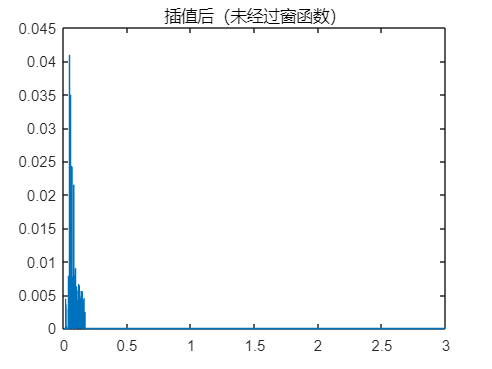

figure
t = [1:length(H)]/fs;
plot(t,H');
title("插值后（未经过窗函数）")

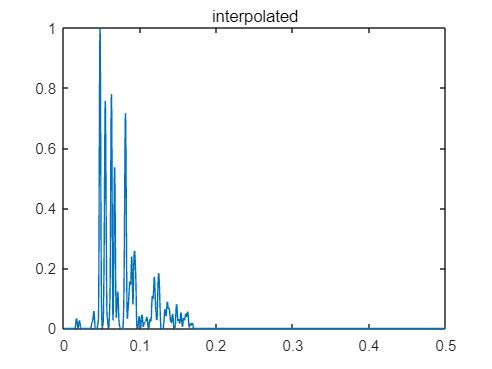

%插值后RIR
W_hann = hann(0.004*fs);
H_output = conv(W_hann,H);
t_output = [1:length(H_output)]/fs;
H_output_norm = H_output./max(H_output);
plot(t_output,H_output_norm');
axis([0 0.5 0 max(H_output_norm)])
title("interpolated")

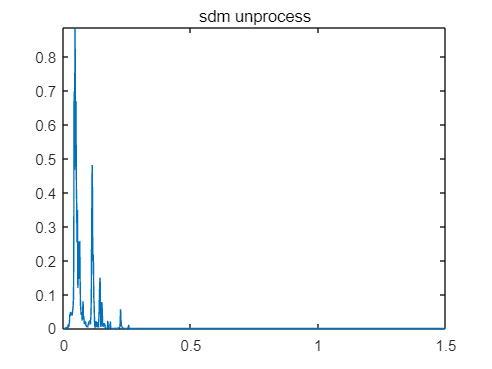

%未经处理的RIR
H_unprocess = pointcloud_rendering(valid_DOA, valid_amp, reci_posi, fs, RT60);
figure
H_unprocess_compute = abs(conv(W_hann,H_unprocess));
t = [1:length(H_unprocess_compute)]/fs;
plot(t,H_unprocess_compute);
axis([0 1.5 0 max(H_unprocess_compute)])
title("sdm unprocess")

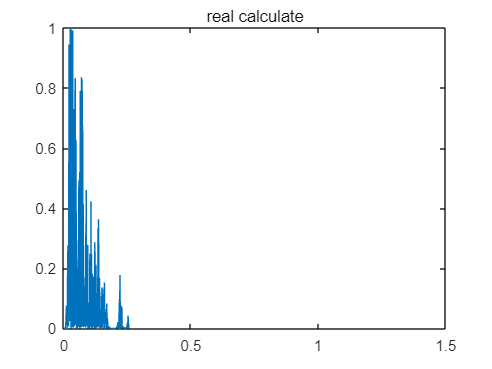

%仿真点RIR
H_compute = abs(conv(W_hann,rir_data(7,:)));
t_compute = [1:length(H_compute)]/fs;
H_compute_norm = H_compute./max(H_compute);
plot(t_compute,H_compute_norm);
axis([0 1.5 0 max(H_compute_norm)])
title("real calculate")

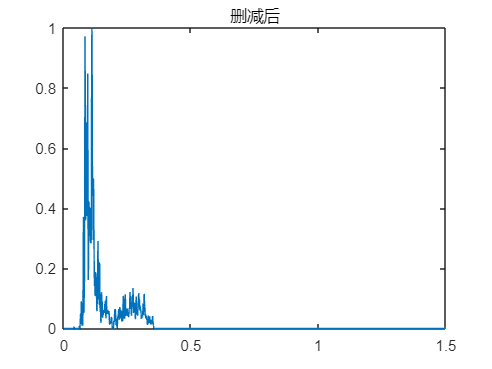

%删减后的仿真点RIR
H_20_compute = abs(conv(W_hann,H_20));
t_20_compute = [1:length(H_20_compute)]/fs;
H_20_compute_norm = H_20_compute./max(H_20_compute);
plot(t_20_compute,H_20_compute_norm);
axis([0 1.5 0 max(H_20_compute_norm)])
title("删减后")

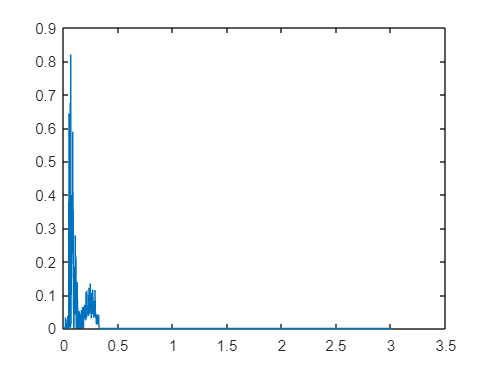

%误差计算
% Compute cross-correlation
[correlation, lag] = xcorr(H_output_norm', H_20_compute_norm');

% Find lag with maximum correlation (indicating best alignment)
[~, maxIndex] = max(correlation);
bestLag = lag(maxIndex);
H_20_compute_norm_shift = circshift(H_20_compute_norm,bestLag);
TAE = abs(H_output_norm'-H_20_compute_norm_shift(1:length(H_output_norm))');
plot(t_output,TAE);

disp(['误差为：', num2str(sum(TAE))]);

误差为：425.5504


% 创建一个示例数据
data = randn(1000, 1); % 生成 1000 个随机数

% 计算直方图
[counts, edges] = histcounts(data);

% 找到计数最多的组别的索引
[maxCount, maxIndex] = max(counts);

% 获取具有最多计数的组别的范围
maxRange = [edges(maxIndex), edges(maxIndex + 1)];

% 输出结果
disp(['具有最多数量的组别的范围：', num2str(maxRange)]);

具有最多数量的组别的范围：-0.3           0


scaleFactor = 6e3;
pointcloud_plot(PCld_3.PointCloud(:,4), PCld_3.PointCloud(:,1:3), scaleFactor )%Axis

无法解析名称 'PCld_3.PointCloud'。

function matrix_show(A)
% 使用 meshgrid 创建 x 和 y 坐标轴
[x, y] = meshgrid(1:size(A, 2), 1:size(A, 1));

% 绘制三维曲面图
surf(x, y, A);

% 设置坐标轴标签
xlabel('Column');
ylabel('Row');
zlabel('Value');
colormap('parula')
colorbar;
% 添加标题
title('Matrix as 3D Surface');
hold on
end

function pointcloud_plot(amp, DOA, scaleFactor, Axis)
if nargin == 3
    Axis = [-60,60,-60,60,-30,30];
end
% 可以根据具体需求设计一个合适的映射关系，这里简单地将幅度信息乘以一个系数作为半径
% 将幅度信息映射到球的半径上
radius = abs(amp * scaleFactor); % scaleFactor 是一个缩放系数，用于调整球的大小
% 绘制散点图
%figure;
scatter3(DOA(:,1), DOA(:,2), DOA(:,3), radius', 'filled');
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Three-dimensional scatter plot with amplitude-dependent spheres');
% colorbar; % 添加颜色条，以显示幅度信息
hold on
% 读取STL文件
[vertices, ~, ~, ~] = stlread('D:\MATLAB\Matlab_HaHa\Degree_project\3D_model_file\zj425.stl');
room = triangulation(vertices.ConnectivityList, vertices.Points./1000);
% 显示STL模型
%trisurf(room, 'FaceColor', [0.8 0.8 0.8], 'FaceAlpha', 0.3, 'EdgeColor', 'none');
axis(Axis)
hold off;
end


function new_amp = kameans_trans(id, original_amp, new_len)
new_amp = zeros(1, new_len);
for i = 1:length(original_amp)
    new_amp(id(i)) = new_amp(id(i)) + abs(original_amp(i));
end
end

function PointCloud_export(DOA, amp, str,mic_position)
PointCloud = [DOA amp];
% 将数字转换为字符串
ad = num2str(abs(mic_position(2,7)));

% 构造文件名
filename = ['PointCloud_', str, '_', ad, '.mat'];

% 保存数据到文件中
save(filename, 'PointCloud');
end

function h = pointcloud_rendering(loca, pres, reci_loca, fs, RT60)
fly_dist = sum((loca-repmat(reci_loca,length(loca),1)).^2,2).^0.5;
arr_time = fly_dist/345; %距离除以声速得到接收时的时间
[arr_time_sorted, sorted_order] = sort(arr_time);
t = zeros(ceil(RT60/1000*fs*2),1);
for k = 1:length(arr_time_sorted)
    t(floor(arr_time_sorted(k)*fs)) = t(floor(arr_time_sorted(k)*fs))+abs(pres(sorted_order(k)));
end
h = t;
end

## Create visualization struct with the given parameters

% plane = 'lateral'; % visualization plane
% DOI = 'backward'; % direction of integration
% plotStyle = 'fill'; % plotting style, fill or line
% name = 'ZJ classroom 425'; % title
% res = 1; % DOA resolution of the polar response
% t = [0 2 5 20]; % time indices of interest
% colors = parula(length(t)); % colormap
% dBSpacing = -12:6:0; % resolution of the dB grid
% DOASpacing = 30; % resolution of the DOA grid
% lw = zeros(size(t)); % no line
% showGrid = true; % grid in the visualization
% dBDynamics = 42; % dynamics in dB

## Create a struct for visualization with a set of parameters

% v = createVisualizationStruct('fs',fs,...
%     'Plane',plane,'DOI',DOI,'name',name,'res',res,...
%     'dBSpacing',dBSpacing,'Colors',colors,'DOASpacing',DOASpacing,...
%     'linewidth',lw,'Showgrid',showGrid,'PlotStyle',plotStyle,...
%     't',t); % Load default values
% % struct v can also be modified later for other parameters
% % e.g. v.t = [0 5 10 200]
% % For visualization purposes, set the text interpreter to latex
% set(0,'DefaultTextInterpreter','latex')

## Draw analysis parameters and impulse responses

% parameterVisualization(P, v);

## Draw time-frequency visualization

% % Drawing only the lateral plane
% timeFrequencyVisualization(P, v)
% 

## Draw the spatiotemporal visualization

% spatioTemporalVisualization(P, DOA, v)
% %使用 sphere 定义向量 x、y 和 z。
% 
% [X,Y,Z] = sphere(16);
% x = [0.5*X(:); 0.75*X(:); X(:)];
% y = [0.5*Y(:); 0.75*Y(:); Y(:)];
% z = [0.5*Z(:); 0.75*Z(:); Z(:)];
% %定义向量 s 可指定标记大小。
% 
% S = repmat([100,50,5],numel(X),1);
% s = S(:);
% %创建一个三维散点图并使用 view 更改图窗中坐标区的角度。
% 
% figure
% scatter3(x,y,z,s)
% view(40,35)
% scatter3(1,1,1,10000)
